clc
clear all

data = load('gdata.mat')

data = struct with fields:
    rhox: [100×1 double]
       x: [500×1 double]
      dn: [500×1 double]


dn = data.dn;
x = data.x;
rhox = data.rhox;

a = 0; b = 1000; n = 100; m = 500;

R = 6.67428e-11; % Newton's gravitational constant
A = 1;
h = 25 - sqrt(A/pi);

dxc = (b-a)/n;

g = @(xc,x) (R*h./((xc - x).^2 + h^2)^(3/2));
xc = [];
for j = 1:n
    xc = [xc a + (dxc/2) + (j-1)*dxc]; %form xc
end
xc;

G = zeros(m,n);
for i = 1:m
    for j = 1:n
        G(i,j) = g(xc(j), x(i)).*dxc;
    end
end

G;

### a. Invert for density perturbations along the pipe transect in kg/m3 using least squares.

ML2 = inv(G'*G)*G'*dn

ML2 = 	1.0e+03 *

    0.1929
   -0.5410
    0.8055
   -0.9389
    1.0252
   -0.9632
    0.7064
   -0.4158
    0.1511
    0.0560


### Interpret the results of your least squares inversion, and analyze the resolution in your model parameter estimates.

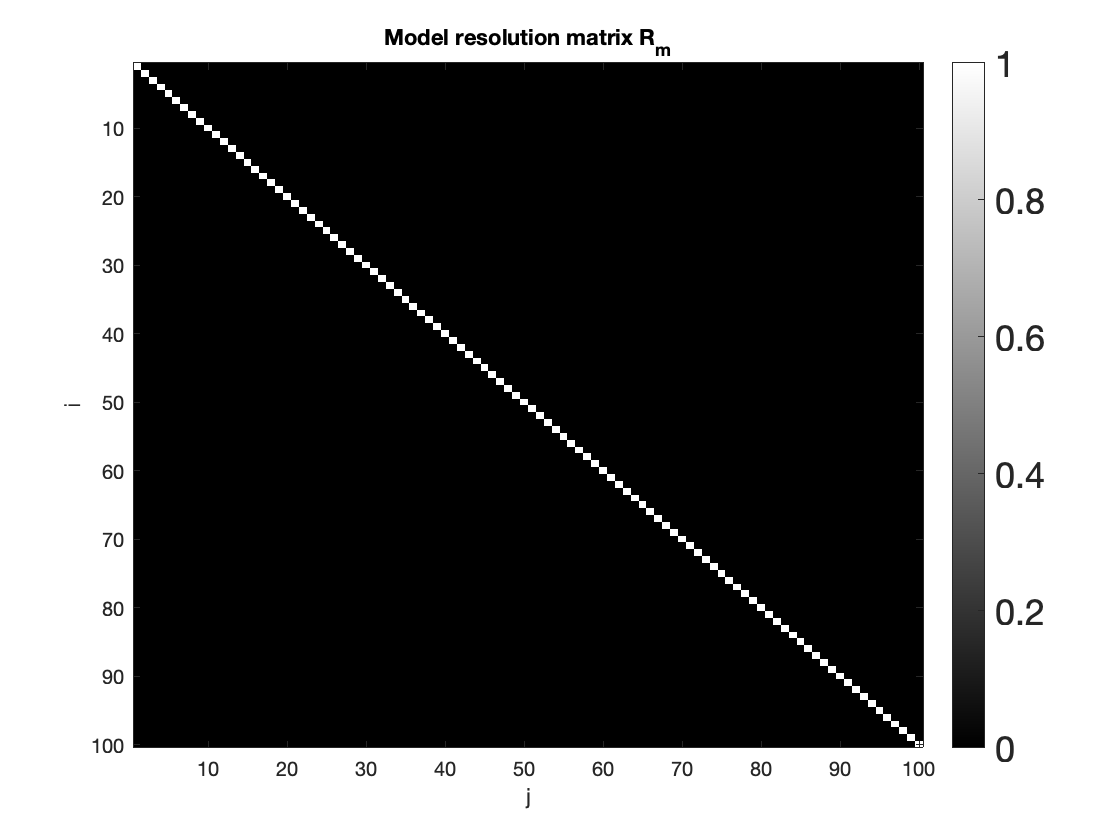

% Get the singular values for the system matrix
[U,S,V] = svd(G);

[m,n] = size(G);

%rank
p=rank(G);

% model resolution matrix
Vp=V(:,1:p);
Rm=Vp*Vp';

figure(1)
clf
colormap('gray')

imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m}')

### b. Invert for density perturbations along the pipe transect in kg/m3 using second order Tikhonov regularization and TGSVD.

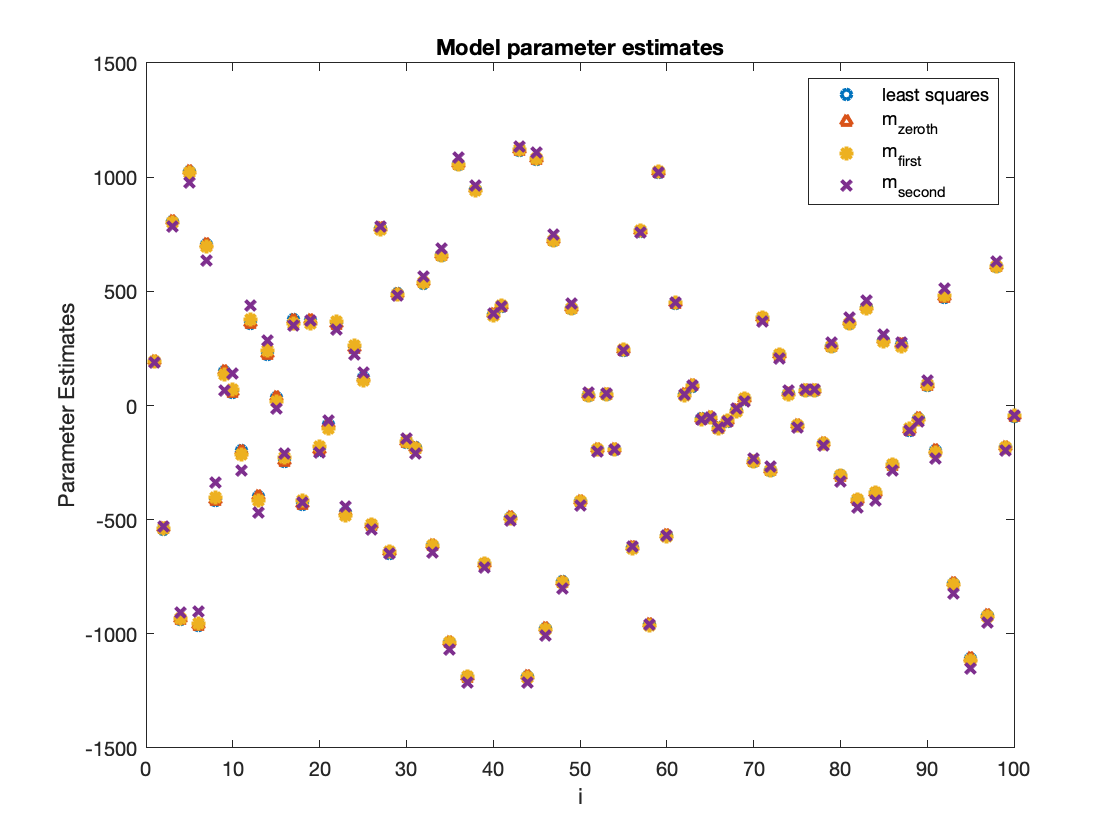

%generate roughening matrices
L1 = get_l_rough(n,1);
L2 = get_l_rough(n,2);

% TGSVD
[U,V,X,S,M] = gsvd(G,eye(n)); Y = (inv(X)');
[U1,V1,X1,S1,M1] = gsvd(G,L1); Y1 = (inv(X1)');
[U2,V2,X2,S2,M2] = gsvd(G,L2); Y2 = (inv(X2)');

% generalized singular values of G and L
lam = @(S) sqrt(diag(S'*S));
mu = @(M) sqrt(diag(M'*M));

k = 0; %m>n
q2 = 100;

Lam = lam(S); Lam1 = lam(S1); Lam2 = lam(S2);

M0 = model_parameters(q2,U,Lam,Y,k,dn,n);
M1 = model_parameters(q2,U1,Lam1,Y1,k,dn,n);
M2 = model_parameters(q2,U2,Lam2,Y2,k,dn,n);

figure(2)
clf
plot(ML2,'o','LineWidth',2,"MarkerSize",5); hold on
plot(M0,'^','LineWidth',2,"MarkerSize",5); 
plot(M1,'*','LineWidth',2,"MarkerSize",5); 
plot(M2,'x','LineWidth',2,"MarkerSize",5); 
legend('least squares','m_{zeroth}','m_{first}','m_{second}')
xlabel('i'); ylabel('Parameter Estimates')
title('Model parameter estimates')

They all have almost the same estimates 

### c. Solve the problem using second-order Tikhonov regularization combined with BVLS and a TGSVD analysis.

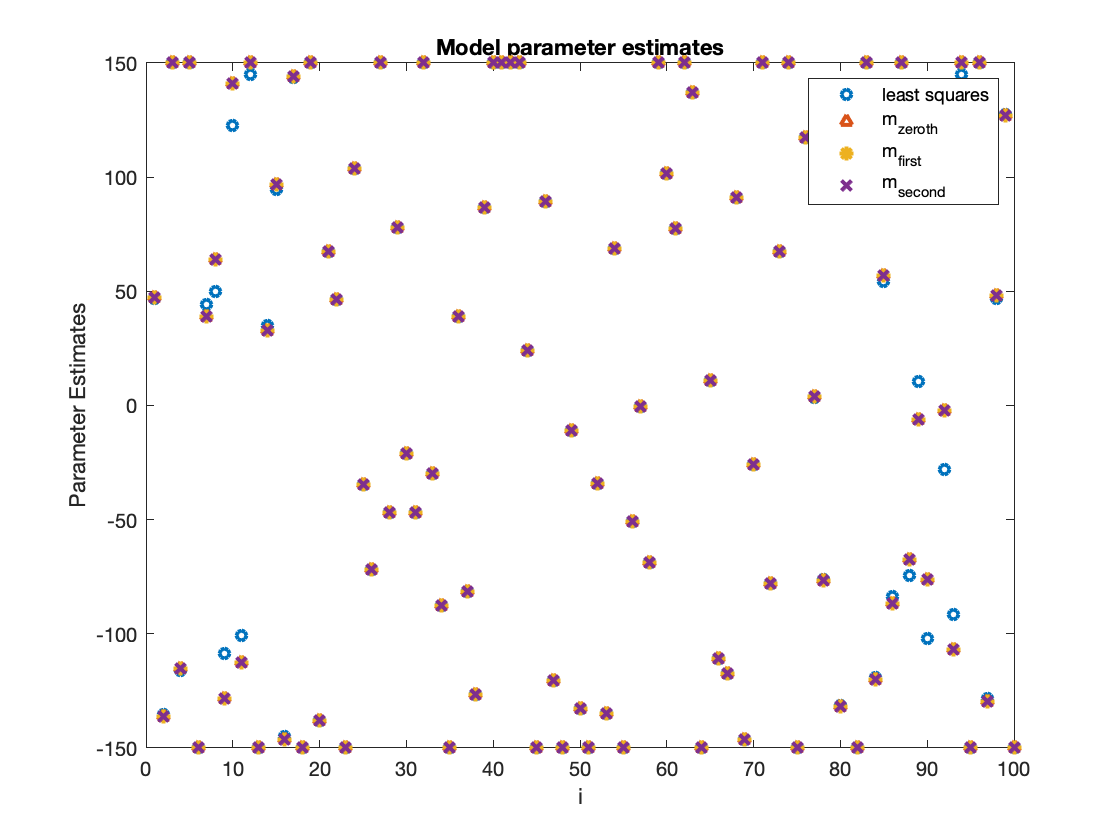

sig = std(dn);
alpha0 = 1e-16;
options = optimset('Display','off');

%zeroth order
L = eye(n);

%m_alpha,L
m_al1 = @(alpha) inv(G'*G + (alpha^2).*(L1'*L1))*(G'*dn);
m_al2 = @(alpha) inv(G'*G + (alpha^2).*(L2'*L2))*(G'*dn);

%zeroth order
L = eye(n);

%first order
delta = 30;
freg = @(alpha) (norm(G*m_al1(alpha) - dn)^2)/(sig^2) + (alpha^2)*norm(L1*m_al1(alpha))^2 - delta;
alpha21 = fsolve(freg,alpha0,options);

%second order
delta = 30; 
freg = @(alpha) (norm(G*m_al2(alpha) - dn)^2)/(sig^2) + (alpha^2)*norm(L2*m_al2(alpha))^2 - delta;
alpha22 = fsolve(freg,alpha0,options);

maxiter = 1000;

alpha = [alpha0 alpha21 alpha22]; 

%generate lower and upper bounds
l= -150.*ones(n,1);
u= 150.*ones(n,1);

%stack the dn matrices
d0 = [dn; zeros(n,1)];
d1 = [dn; zeros(n-1,1)];
d2 = [dn; zeros(n-2,1)];

%stack the matrices
A = [G; alpha(1)*L];
A1 = [G; alpha(2)*L1];
A2 = [G; alpha(3)*L2];

%find positions of 91 and 899 in m
pos = find(xc < 91); pos_91 = pos(end);
pos = find(xc > 899); pos_899 = pos(1);

%setting bounds for xc
c = zeros(n,1); c(pos_91:pos_899) = 0.01*ones(83,1);

%m = bvls(A,d,l,u,maxiter)
ML2 = blf2(G, dn, c, delta, l, u,0);    %least squares
M0 = blf2(A, d0, c, delta, l, u,alpha(1));    
M1 = blf2(A1, d1, c, delta, l, u,alpha(2));    
M2 = blf2(A2, d2, c, delta, l, u,alpha(3));    

figure(3)
clf
plot(ML2,'o','LineWidth',2,"MarkerSize",5); hold on
plot(M0,'^','LineWidth',2,"MarkerSize",5); 
plot(M1,'*','LineWidth',2,"MarkerSize",5); 
plot(M2,'x','LineWidth',2,"MarkerSize",5); hold on
legend('least squares','m_{zeroth}','m_{first}','m_{second}')
xlabel('i'); ylabel('Parameter Estimates')
title('Model parameter estimates')

### Analyze the resolution in your model parameter estimates.

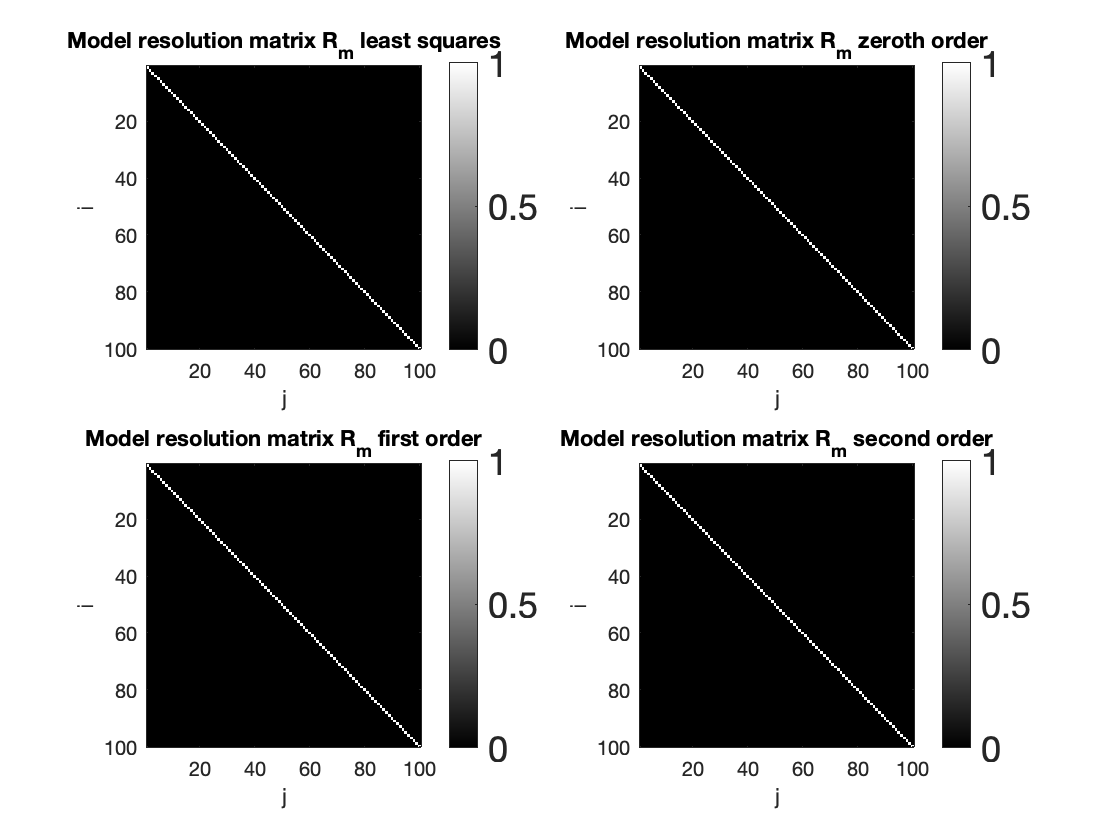

figure(4)
clf
colormap('gray')
subplot(2,2,1)
[U,S,V] = svd(G); p=rank(G);
Vp=V(:,1:p);
Rm=Vp*Vp';
imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m} least squares')

subplot(2,2,2)
[U,S,V] = svd(A); p=rank(A);
Vp=V(:,1:p);
Rm=Vp*Vp';
imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m} zeroth order')

subplot(2,2,3)
[U,S,V] = svd(A1); p=rank(A1);
Vp=V(:,1:p);
Rm=Vp*Vp';
imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m} first order')

subplot(2,2,4)
[U,S,V] = svd(A2); p=rank(A2);
Vp=V(:,1:p);
Rm=Vp*Vp';
imagesc(Rm)
set(colorbar,'Fontsize',18);
xlabel('j')
ylabel('i')
title('Model resolution matrix R_{m} second order')

function [M] = model_parameters(q,U,Lam,Y,k,d,n)
    M = 0;
    for i = n-q+1:n
        M = M + (U(:,i-k)'*d)/(Lam(i))*Y(:,i);
    end
end